%%A little statistics
%%Part 1
%checking the error function
normcdf(0)

ans = 0.5000

normcdf(0.1)

ans = 0.5398

normcdf(0.24)

ans = 0.5948

%checking the inverse of the error function
norminv(0.5)

ans = 0

norminv(0.5398)

ans = 0.0999

norminv(0.5948)

ans = 0.2399

%values match pretty close to inputs
%check probabilities for sigma = 1,2,5
norminv(0.8413)

ans = 0.9998

norminv(0.9772)

ans = 1.9991

norminv(1)

ans = Inf

%close!
%negative numbers would appear if we try
%probability that is below 0.5
norminv(0.3)

ans = -0.5244

%the integral goes from negative inf to z, and
%probability of 1/2 is at z=0
%the negative makes sense because it assumes that 
%we are looking to the right of the mean centered
%at 0
%hence things on the left would be negative

%%Part2
dist = random('Lognormal',5.,0.01,[1,100000])

dist =   150.4609  145.8947  148.2615  148.0553  148.8877  148.8782  147.1351  148.3686  148.1687  149.3477  150.0446  150.0686  147.1369  148.5280  146.6221  146.7697  148.4030  150.7053  147.2753  148.9654  148.0787  150.0808  146.8056  148.4615  149.2355  150.0556  150.7228  148.5407  146.2159  147.3156  146.8460  151.9429  147.5023  149.5276  148.1279  149.7379  147.2824  146.3465  146.3171  149.1395  148.1501  148.1225  150.5346  148.8465  148.7070  150.7883  147.2240  149.4507  149.6577  148.0519


histogram(dist,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on
x = linspace(141,158,1000)

x =   141.0000  141.0170  141.0340  141.0511  141.0681  141.0851  141.1021  141.1191  141.1361  141.1532  141.1702  141.1872  141.2042  141.2212  141.2382  141.2553  141.2723  141.2893  141.3063  141.3233  141.3403  141.3574  141.3744  141.3914  141.4084  141.4254  141.4424  141.4595  141.4765  141.4935  141.5105  141.5275  141.5445  141.5616  141.5786  141.5956  141.6126  141.6296  141.6466  141.6637  141.6807  141.6977  141.7147  141.7317  141.7487  141.7658  141.7828  141.7998  141.8168  141.8338


pd = makedist("Lognormal","mu",5.,"sigma",0.01)

pd =   LognormalDistribution

  Lognormal distribution
       mu =    5
    sigma = 0.01


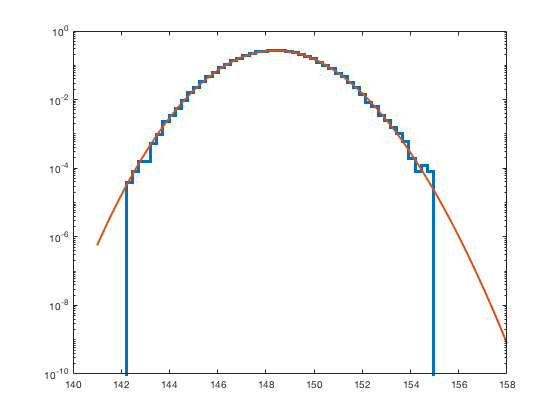

plot(x,pdf(pd,x),"LineWidth",2)
set(gca,'YScale','log')

%%Part 3
%value = 151
%what is the probability that the measurement of
%value 151 isn't noise or is not produced by the
% signal free distribution, instead being
% a physical measurement, if higher is signal-like
%another way to see this is the probability that
%the selected value or anything smaller is given
%by the probability distribution

%integral from -inf to 151 of pd (probability
%distribution)
cdf(pd,151)

ans = 0.9580

%convert this probability into sigma
norminv(0.9580)

ans = 1.7279

%the sigma is 1.7279

%%Part 4
%try values 148,140,200,166,120,150
%see the associated sigmas
cdf(pd,148)

ans = 0.3902

norminv(cdf(pd,148))

ans = -0.2788

cdf(pd,140)

ans = 2.6773e-09

norminv(cdf(pd,140))

ans = -5.8358

cdf(pd,200)

ans = 1

norminv(cdf(pd,200))

ans = Inf

cdf(pd,166)

ans = 1

norminv(cdf(pd,166))

ans = Inf

cdf(pd,120)

ans = 1.6196e-100

norminv(cdf(pd,120))

ans = -21.2508

%as expected, values within the distribution
%yield answers between 0 and 1
%values much higher than the distribution
%yield answers close to 1
%values much lower than the distribution give
%negative probabilities

%%Poison Distribution
x = 0:10

x =      0     1     2     3     4     5     6     7     8     9    10


poisDist = makedist("Poisson", 'lambda',7)

poisDist =   PoissonDistribution

  Poisson distribution
    lambda = 7


%lambda is the main parameter in a Poisson
%distribution, changing lambda changes
%how "large" the distribution is
subplot(2,3,4)
stairs(x-2,pdf(poisDist,x),"LineWidth",2)
set(gca,'YScale','log')
title('lambda = 7')
subplot(2,3,5)
poisDist2 = makedist("Poisson",'lambda',4)

poisDist2 =   PoissonDistribution

  Poisson distribution
    lambda = 4


stairs(x-2,pdf(poisDist2,x),"LineWidth",2)
set(gca,'YScale','log')
title('lambda = 4')
subplot(2,3,6)
poisDist3 = makedist("Poisson",'lambda',15)

poisDist3 =   PoissonDistribution

  Poisson distribution
    lambda = 15


stairs(x-2,pdf(poisDist3,x),"LineWidth",2)
set(gca,'YScale','log')
title('lambda = 15')
subplot(2,3,1)
stairs(x-2,pdf(poisDist,x),"LineWidth",2)
title('lambda = 7')
subplot(2,3,2)
stairs(x-2,pdf(poisDist2,x),"LineWidth",2)
title('lambda = 4')
subplot(2,3,3)
stairs(x-6,pdf(poisDist3,x),"LineWidth",2)
title('lambda = 15')
%changing x range well...changes the range
%that values of x may span, and thus the 
%number of entries
x = 0:100

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


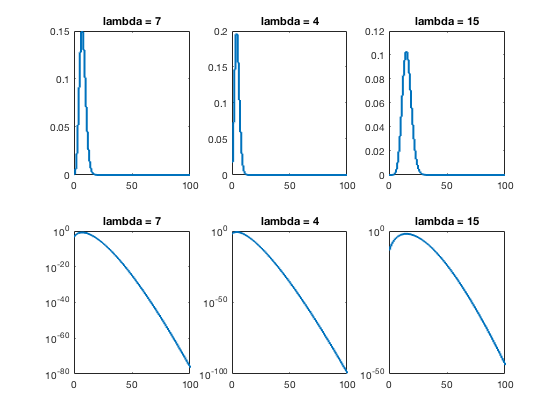

subplot(2,3,4)
stairs(x,pdf(poisDist,x),"LineWidth",2)
set(gca,'YScale','log')
title('lambda = 7')
subplot(2,3,5)
stairs(x,pdf(poisDist2,x),"LineWidth",2)
set(gca,'YScale','log')
title('lambda = 4')
subplot(2,3,6)
stairs(x,pdf(poisDist3,x),"LineWidth",2)
set(gca,'YScale','log')
title('lambda = 15')
subplot(2,3,1)
stairs(x,pdf(poisDist,x),"LineWidth",2)
title('lambda = 7')
subplot(2,3,2)
stairs(x,pdf(poisDist2,x),"LineWidth",2)
title('lambda = 4')
subplot(2,3,3)
stairs(x,pdf(poisDist3,x),"LineWidth",2)
title('lambda = 15')

%hypothetical question
%what is the probability that the measurement of
%value 6 isn't noise or is not produced by the
% signal free distribution, instead being
% a physical measurement, if higher is signal-like
%another way to see this is the probability that
%the selected value or anything smaller is given
%by the probability distribution
cdf(poisDist,6)

ans = 0.4497

norminv(cdf(poisDist,6))

ans = -0.1264

%sigma value is given by result of norminv
%so sigma is -0.1264

I just realized I can do text like this

The probabilities and sigmas being discrete implies that recording a ton of events and taking an average does not necessarily yield something of meaningful value — the average of 100 trials may be a result that cannot be achieved within any trial, thus representing incorrect probabilities and 'sigmas.'

There is no issue with parameters being continuous, despite the distribution being discrete, because like with the example of the dice and mean, the sum of discrete values divided by the number of terms in no way has to be an integer, so in general, it will have a continuous spectrum.